## **PID regulacija sustava automatskog navodnjavanja**

clc; clear; close all;

### Prijenosna funkcija i stabilnost sustava 

%% Parametri sustava
kp  = 1;      % ml/s po jedinici PID izlaza
k12 = 0.3;    % 1/min - infiltracija iz zone1 u zone2
ke  = 0.2;    % 1/min - prosječni koef. isparavanja
V2  = 1;      % m^3 - površinski sloj

%% Prijenosna funkcija G0(s)
s = tf('s');
G0 = (kp * k12) / (V2 * (s + k12) * (s + ke));

disp('Prijenosna funkcija G0(s):');

Prijenosna funkcija G0(s):


G0


G0 =
 
         0.3
  ------------------
  s^2 + 0.5 s + 0.06
 
Continuous-time transfer function.
Model Properties



pole(G0)

ans =    -0.3000
   -0.2000


Odziv na skok

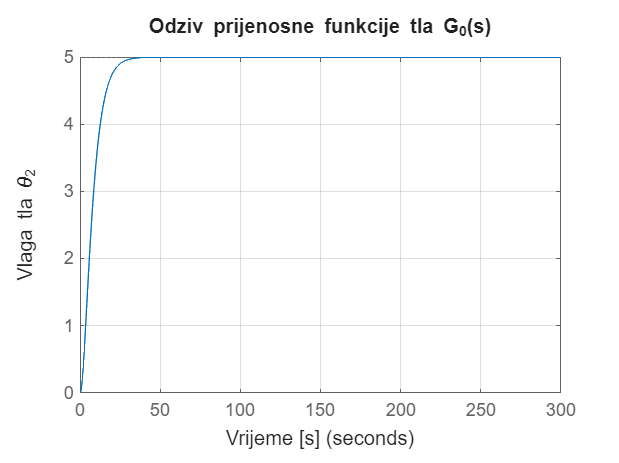

figure;
step(G0, 300);   % 300 s simulacije
grid on;
title('Odziv prijenosne funkcije tla G_0(s)');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla \theta_2');

Karakteristike odziva

info = stepinfo(G0);

disp('Karakteristike odziva:');

Karakteristike odziva:


fprintf('Vrijeme porasta: %.2f s\n', info.RiseTime);

Vrijeme porasta: 14.13 s


fprintf('Vrijeme stabilizacije: %.2f s\n', info.SettlingTime);

Vrijeme stabilizacije: 24.77 s


fprintf('Maksimalna vrijednost: %.2f\n', info.Peak);

Maksimalna vrijednost: 5.00


fprintf('Nadvišenje: %.2f %%\n', info.Overshoot);

Nadvišenje: 0.00 %


Provjera nula 

pole(G0)

ans =    -0.3000
   -0.2000


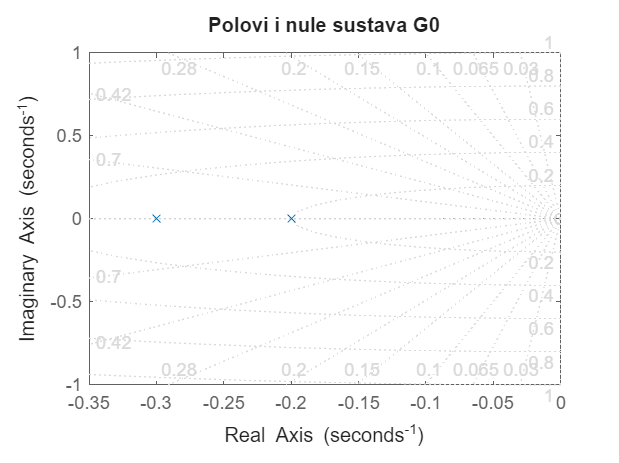


pzmap(G0)   % crtanje polova i nula
grid on
title('Polovi i nule sustava G0')

*Ovaj sustav je stabilan budući da su svi polovi u lijevoj poluravnini.*

### PID parametri

Kp = 1.2;
Ki = 0.05;
Kd = 0.1;
Gr = pid(Kp, Ki, Kd);

disp('PID regulator Gr(s):');

PID regulator Gr(s):


Gr


Gr =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.2, Ki = 0.05, Kd = 0.1
 
Continuous-time PID controller in parallel form.
Model Properties


Zatvorena petlja

T_pid = feedback(G0 * Gr, 1);

disp('Zatvorena petlja T_pid(s):');

Zatvorena petlja T_pid(s):


T_pid


T_pid =
 
     0.03 s^2 + 0.36 s + 0.015
  -------------------------------
  s^3 + 0.53 s^2 + 0.42 s + 0.015
 
Continuous-time transfer function.
Model Properties


Pregled polova za Gr * G0

L = Gr * G0


L =
 
  0.03 s^2 + 0.36 s + 0.015
  -------------------------
   s^3 + 0.5 s^2 + 0.06 s
 
Continuous-time transfer function.
Model Properties


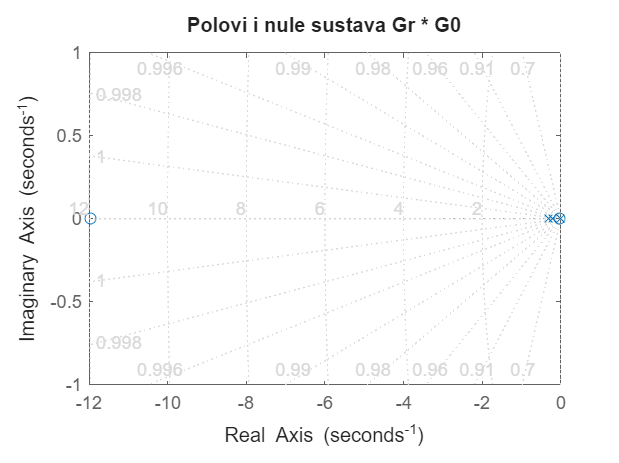

pzmap(L)   % crtanje polova i nula
grid on
title('Polovi i nule sustava Gr * G0')

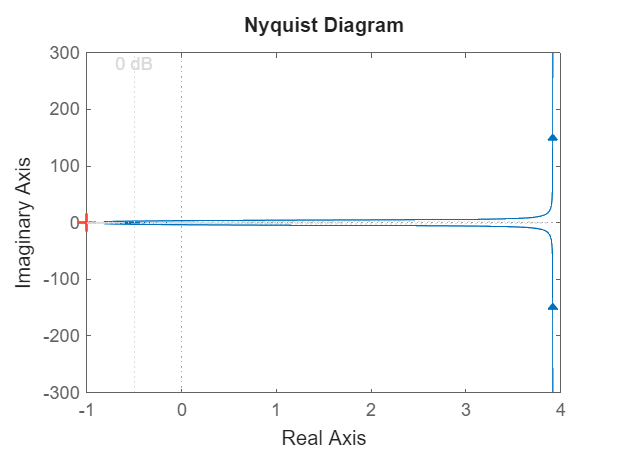


nyquist(L)
grid on

Odziv na željenu vrijednost

% Željena vlaga [%]
desired_moisture = 70

desired_moisture = 70

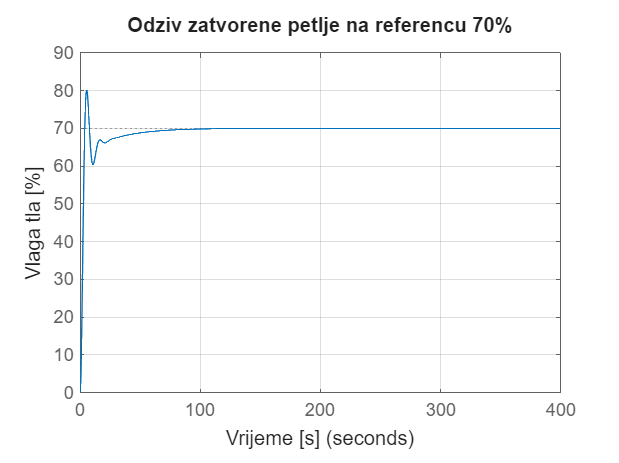


figure;
step(desired_moisture*T_pid, 400);
grid on;
title('Odziv zatvorene petlje na referencu 70%');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla [%]');


info = stepinfo(70*T_pid);

fprintf('Vrijeme stabilizacije: %.2f s\n', info.SettlingTime);

Vrijeme stabilizacije: 45.91 s


fprintf('Nadvišenje: %.2f %%\n', info.Overshoot);

Nadvišenje: 14.49 %


### **Usporedba s prijenosom bez povratne veze**

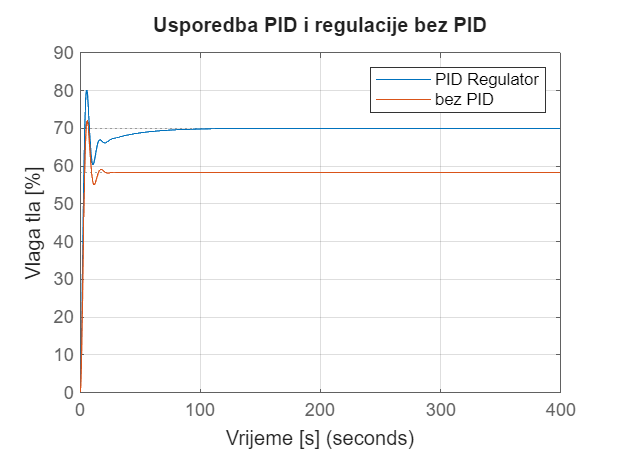

T_on_off = feedback(G0, 1); % G0 bez PID-a, samo otvorena petlja
%% Odziv na skok za PID
figure;
step(desired_moisture * T_pid, 400);
hold on;

%% Odziv na skok za On/Off
step(desired_moisture * T_on_off, 400);
hold off;

grid on;
title('Usporedba PID i regulacije bez PID');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla [%]');
legend('PID Regulator', 'bez PID');


%% Informacije o odzivu
info_pid = stepinfo(desired_moisture * T_pid);
info_on_off = stepinfo(desired_moisture * T_on_off);

fprintf('PID Regulacija:\n');

PID Regulacija:


fprintf('Vrijeme stabilizacije: %.2f s\n', info_pid.SettlingTime);

Vrijeme stabilizacije: 45.91 s


fprintf('Nadvišenje: %.2f %%\n', info_pid.Overshoot);

Nadvišenje: 14.49 %


fprintf(' ')

fprintf('Regulacija bez PID:\n');

Regulacija bez PID:


fprintf('Vrijeme stabilizacije: %.2f s\n', info_on_off.SettlingTime);

Vrijeme stabilizacije: 14.00 s


fprintf('Nadvišenje: %.2f %%\n', info_on_off.Overshoot);

Nadvišenje: 23.68 %


Sustav bez PID regulatora ne postiže zadanu referencu zbog stacionarne pogreške karakteristične za sustave bez integracijskog djelovanja, što rezultira stabilizacijom izlaza na približno 58% umjesto željenih 70%.